# Lorenz Multiple Parameter Identification

The Lorenz system considered in this example is defined as,


$$\dot{x}_1(t)=\theta_1(x_2(t)-x_1(t)),$$



$$\dot{x}_2(t)=x_1(t)(\theta_2-x_3(t))-x_2(t),$$



$$\dot{x}_3(t)=x_1(t)x_2(t)-\theta_3x_3(t),$$



$$y(t)=x_1(t),$$


where the states $x(t)\in\mathbb{R}^3$ and the parameters $\theta\in\mathbb{R}^3$. In this example the underlying true system is initialized at initial states $x^{\star}(0)=[-2.5;-0.5;20]$ and parameters $\theta^{\star}=[10;28;8/3]$ characterizing the true system as chaotic. The goal of this example is to use Spline-MHE algorithm to use the true model output $y(t)=x_1(t)$ corrupted with Gaussian noise to estimate the model initial states $x^\ast(0)$ and identify the model parameters $\theta^\ast$.

#### Generate Noisy Data

The following code generates and plots the output trajectory from the true model and corrupts it with Gaussian noise:

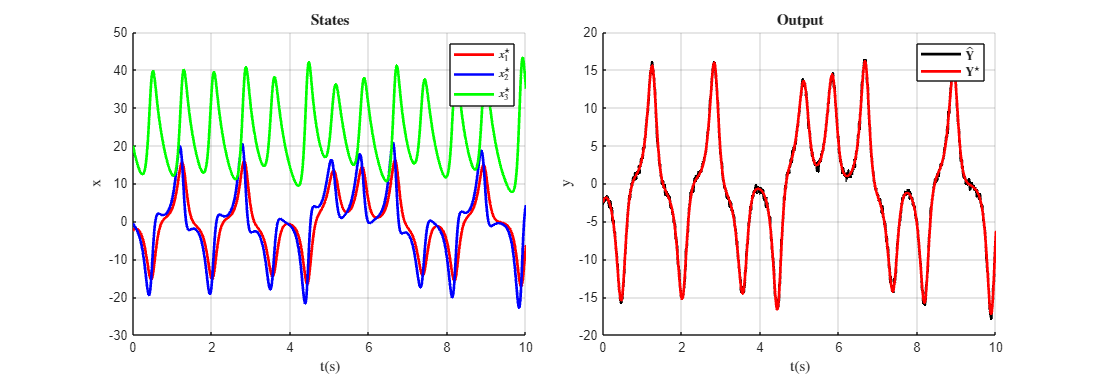

clear
global iteration_data Sol;
addpath("Support_Functions\");

T = 10; % simulation time
N = 1000; % number of time step intervals
dt = T/N; % time step size

n_x = 3;
n_y = 1;
n_theta = 3;

% True Initial condition and parameter values
x0_star = [-2.5;-0.5;20];
theta_star = [10;28;8/3];

true_param = {x0_star,theta_star};

% Simulate true model
[x_star,y_star] = Lorenz_sim(true_param,N,dt,10,1);

#### Initialize Spline-MHE

For initializing the Spline-MHE algorithm, the initial guess of $x(0)$ and $\theta$, the smoothing spline estimate of noisy data $\mathbf{\hat{Y}}^{est}$, along with the hyperparameter choices are required. Here the initial $x(0)$ and $\theta$ are arbitrarily chosen by linearly scaling $x^\star(0)$ and $\theta^\star$ using scaling factors $r_x
$ and $r_\theta$. The smoothing spline estimate $\mathbf{\hat{Y}}^{est}=\big(\Phi\Phi^\dagger_{\lambda,\delta}\mathbf{\hat{Y}}^\top\big)^\top$ of the noisy data for $\Phi^\dagger_{\lambda,\delta}=\big(\Phi^\top\Phi+\lambda\Phi^{(\delta)\top}\Phi^{(\delta)}\big)^{-1}\Phi^\top$ is obtained by first finding a minimizing value of the smoothness factor $\lambda$ for a chosen spline derivative order $\delta$ using a Generalized Cross-Validation (GCV) scheme. The Spline-MHE hyperparameter can then be selected based on the heuristics presented in the paper. For demonstration purposes, the hyperparameter choices for number of moving horizons $n_h=1$, number of multiple shooting spline segments over a horizon $n_s=20$, spline order $n_p=3$, number of knots per spline segment $n_\tau=8$, and a weighting matrix $\mathbf{W=I}$ are chosen for this example. The following code initializes the Spline-MHE algorithm:

% Initial state and parameter Scaling factors 
r_x = 2;
r_theta = 2;

x0_init = x0_star*r_x; % x(0) initial guess
theta_init = theta_star*r_theta; % theta initial guess

% lambda estimate using GCV




n_mhe = 1;
n_iter = 20;

p = 3;
o = p+5;

N = N/n_mhe;
n_poly = N/n_iter;


% Initial condition for x and initial parameter guess

x0 = x0_true*r_states;
xi0 = xi_true*r_param;

init_param = {xi0,x0};
[x_sim,y_sim] = Lorenz_sim(init_param,N,dt);

% Wx = mean(abs(x_sim-min(y_measured,[],2))./abs(max(x_sim,[],2)-min(x_sim,[],2)),2);
% Wy = mean(abs(y_sim-min(y_measured,[],2))./abs(max(y_sim,[],2)-min(y_sim,[],2)),2);

Wx = [1;1;1];
Wy = [1];

figure()
hold on 

plot(linspace(0,T,N+1)',x_sim(1,:).*Wx(1,:),'r',LineWidth=2)
plot(linspace(0,T,N+1)',x_sim(2,:).*Wx(2,:),'b',LineWidth=2)
plot(linspace(0,T,N+1)',x_sim(3,:).*Wx(3,:),'g',LineWidth=2)
plot(linspace(0,T,N+1)',y_sim.*Wy,'k',LineWidth=2)

hold off
grid on



tidx = find((rem(1:N,n_poly)==0))+1;
idx_x = [reshape(1:n_iter*(n_poly),[],n_iter)' tidx'];

t_all = linspace(0,N,N+1);
t = reshape(t_all(1:end-1),[],n_iter)';
t = [t t_all(tidx)'];

knots = linspace(min(t(1,:)), max(t(1,:)), o);
knots = augknt(knots, p + 1);
B = bsplineBasisMatrix(t(1,:), knots, p);

C_init = {};
for i = 1:n_states
    c_int = [];
    for k=1:n_iter
        X = x_sim(i,idx_x(k,:));
        
        c_int = [c_int (B'*B)\(B'*X')];
    end
    C_init{end+1} = c_int;
end


Cest_init = {};
for i = 1:n_outputs
    c_int = [];
    for k=1:n_iter
        Y = y_sim(i,idx_x(k,:));
        
        c_int = [c_int (B'*B)\(B'*Y')];
    end
    Cest_init{end+1} = c_int;
end

spline_param = [p,o];

